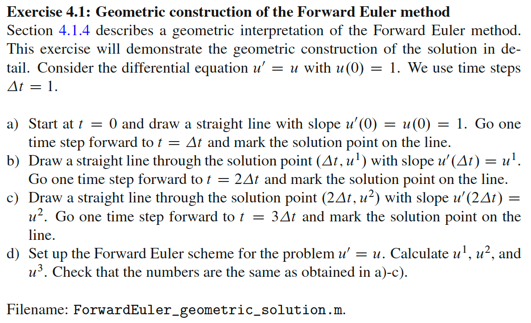

a)

Her får vi en linje fra (0,0) til u_0 + DeltaT*u'_0 = (1,2)

b)

Her får vi en linje fra (1,2) til (2,4)

c)

Her får vi en linje fra (2,4) til (3,8)

d)

%define input parameters
dt = 1;
t_end = 3;
N = t_end/dt; %number of steps

u = zeros(N + 1, 1); %initialize array for u-values
t = 0:dt:t_end; %time array

%start values
u(1) = 1;

%run forward Euler method with for loop
for i = 1:N
    u(i+1) = u(i) + dt * u(i);
end

%display results
disp('Time and solution values:')

Time and solution values:


disp(table(t', u, 'VariableNames', {'Time', 'u'}))

    Time    u
    ____    _

     0      1
     1      2
     2      4
     3      8



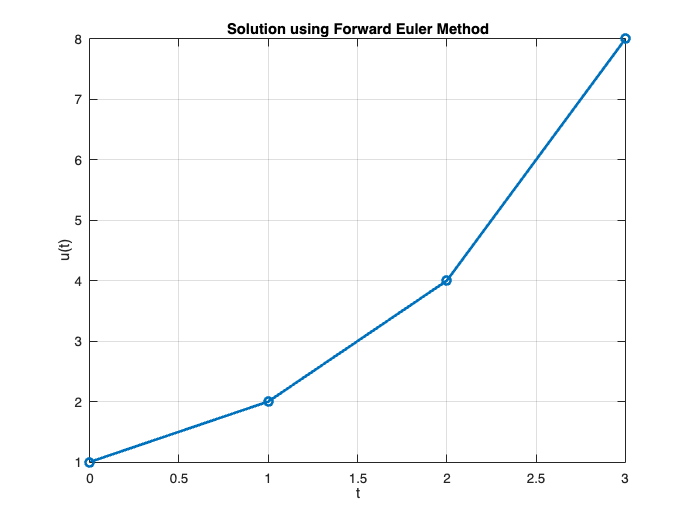


%plot solution
figure;
plot(t, u, '-o', 'LineWidth', 2);
xlabel('t');
ylabel('u(t)');
title('Solution using Forward Euler Method');
grid on;

Dette stemmer overens med det forventede resultat.